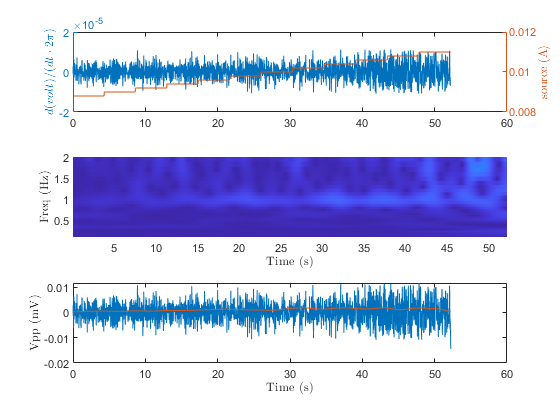

clear;clf(); clc;
filepath = "C:\Users\iCalculate\Desktop\211test\401\#4\#4-1 VT 77K step 8.8-11mA 11um.csv";
data=csvread(filepath,1,0);
volt = data(:,4);
curr = data(:,5);
time = data(:,6);
source = data(:,7);
% load(filepath);
% time = t; source = curr;
if min(diff(time))<0
    t_stop_idx = find(diff(time)<0);
    v = data(1:t_stop_idx,4);
    c = data(1:t_stop_idx,5);
    s = data(1:t_stop_idx,7);
    t = data(1:t_stop_idx,6);
    time = linspace(t(1),t(end),size(t,1));
    volt = interp1(t,v,time);
    curr = interp1(t,c,time);
    source = interp1(t,s,time,"next");
else
    t = time;
    time = linspace(time(1),time(end),size(time,1));
    volt = interp1(t,volt,time);
    curr = interp1(t,curr,time);
    source = interp1(t,source,time,"next");
end

[d_volt, rmind] = rmoutliers(diff(volt)./diff(time));

f1 = figure(1);f1.Position(3:4) = [560 700]; 
subplot(311);
[AX,Ha,Hb] = plotyy(time(~rmind),d_volt/(2*pi),time,source);
set(get(AX(1),'ylabel'),'string','$ d(volt)/(dt\cdot2\pi) $','interpreter','latex');
set(get(AX(2),'ylabel'),'string','source (A)','interpreter','latex');
subplot(312);
time_diff = time(~rmind);
wt_volt = interp1(time_diff,d_volt,time,"makima");
[cfs,frq] = cwt(wt_volt, 1/mean(diff(time)));
surface(time,frq,abs(cfs));axis tight;shading flat
ylim([0.1,2])
xlabel('Time (s)','Interpreter',"latex");
ylabel('Freq (Hz)',"Interpreter","latex");
subplot(313);
plot(time,1e3*wt_volt/(2*pi),time,1e3*abs(cfs(44,:))/(2*pi));
xlabel('Time (s)','Interpreter',"latex");
ylabel('Vpp (mV)',"Interpreter","latex");

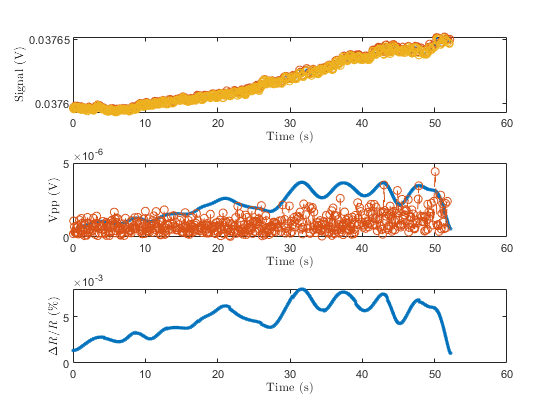


f2 = figure(2);%f2.Position(3:4) = [560 700]; 
volt_rmbg = volt-[0, cumsum(diff(volt).*double(rmind))];
[pks, plocs] = findpeaks(volt_rmbg);
[vas, vlocs] = findpeaks(-volt_rmbg);
subplot(311);
plot(time,volt_rmbg);hold on
scatter(time(plocs),pks);
scatter(time(vlocs),-vas);hold off
xlabel('Time (s)','Interpreter',"latex");
ylabel('Signal (V)',"Interpreter","latex");
idx = min(size(plocs,2),size(vlocs,2));
vpp = (pks(1:idx-2)+pks(2:idx-1))/2+vas(1:idx-2);
subplot(312);
leakage_rate = 0.5;
plot(time,1*abs(cfs(44,:))/(2*pi)/(leakage_rate),'.', ...
    time(vlocs(1:idx-2)),vpp,'o--');
xlabel('Time (s)','Interpreter',"latex");
ylabel('Vpp (V)',"Interpreter","latex");
subplot(313);
vpp_cwt = 1*abs(cfs(44,:))/(2*pi)/(leakage_rate);
delta_R = vpp_cwt./curr;
R = volt./curr;
delta_R_rate = delta_R./R;
plot(time,delta_R_rate*100,'.');
xlabel('Time (s)','Interpreter',"latex");
ylabel('$ \Delta R/R $ (\%)',"Interpreter","latex");

f3 = figure(3);f3.Position(3:4) = [560 700]; 
[G, Bias_curr] = findgroups(source);
DeltaR_mean = splitapply(@mean,delta_R,G);
Vpp_mean = splitapply(@mean,vpp_cwt,G);
Rrate_mean = splitapply(@mean,delta_R_rate,G);
T = table(Bias_curr',Vpp_mean',DeltaR_mean',100*Rrate_mean');
T.Properties.VariableNames = ["I_bias","Vpp","DeltaR","R_rate"]

T = 12×4 table
    I_bias       Vpp          DeltaR       R_rate  
    ______    __________    __________    _________

    0.0088    8.3399e-07    9.4772e-05    0.0022183
     0.009    1.0175e-06    0.00011306    0.0026319
    0.0092    1.2219e-06    0.00013283    0.0030728
    0.0094    1.6007e-06     0.0001703    0.0039125
    0.0096    2.3252e-06    0.00024222    0.0055223
    0.0098    2.1448e-06    0.00021887    0.0049471
      0.01    2.1876e-06    0.00021877    0.0048976
    0.0102    3.2441e-06    0.00031806    0.0070446
    0.0104    3.3262e-06    0.00031984    0.0070001
    0.0106    3.1719e-06    0.00029923    0.0064735
    0.0108    2.8099e-06    0.00026018    0.0055458
     0.011    2.6447e-06    0.00024044    0.0050409


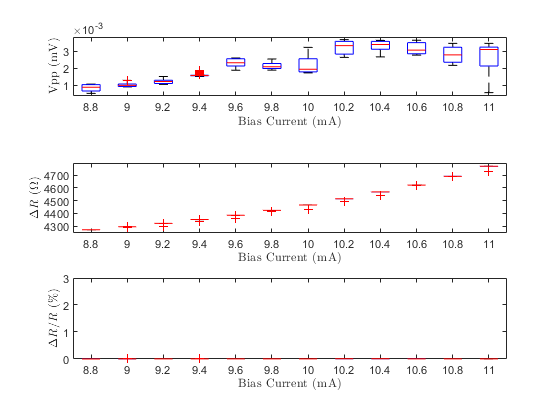

subplot(311);
boxplot(1e3*vpp_cwt,source*1e3);
xlabel('Bias Current (mA)',"Interpreter","latex");
ylabel('Vpp (mV)',"Interpreter","latex")
subplot(312);
boxplot(1e3*R,source*1e3);
xlabel('Bias Current (mA)',"Interpreter","latex");
ylabel('$ \Delta R $ ($\Omega$)',"Interpreter","latex")
subplot(313);
boxplot(1e2*delta_R_rate,source*1e3);ylim([0,3])
xlabel('Bias Current (mA)',"Interpreter","latex");
ylabel('$ \Delta R/R $ (\%)',"Interpreter","latex")